Dataset setting

#change gTruth

sourceData = gTruth.DataSource.Source;
labelData = gTruth.LabelData;
%sourceData = gTruth.DataSource.Source(1:300);
%labelData = gTruth.LabelData(1:300,:);
labelFields = labelData.Properties.VariableNames;
data = struct();
for i = 1:numel(sourceData)
    data(i).source = sourceData{i};
    for j = 1:numel(labelFields)
        data(i).(labelFields{j}) = labelData{i, j};
    end
end


Presession

#change gTruth

detector = yolov4ObjectDetector("tiny-yolov4-coco")

detector =   yolov4ObjectDetector with properties:

             Network: [1×1 dlnetwork]
         AnchorBoxes: {2×1 cell}
          ClassNames: {80×1 cell}
           InputSize: [416 416 3]
    PredictedBoxType: 'axis-aligned'
           ModelName: 'tiny-yolov4-coco'


imds = imageDatastore(gTruth.DataSource.Source);
blds = boxLabelDatastore(gTruth.LabelData(:,1:end));
ds = combine(imds,blds);
inputSize = [416 416 3];
trainingDataForEstimation = transform(ds,@(data)preprocessData(data,inputSize));

numAnchors = 6;
[anchors, meanIoU] = estimateAnchorBoxes(trainingDataForEstimation,numAnchors);
area = anchors(:,1).*anchors(:,2);
[~,idx] = sort(area,"descend");
anchors = anchors(idx,:);
anchorBoxes = {anchors(1:3,:);anchors(4:6,:)};
classes = {'bottle','can','pouch'};
detector = yolov4ObjectDetector("tiny-yolov4-coco",classes,anchorBoxes,InputSize=inputSize);

options = trainingOptions("sgdm", ...
    InitialLearnRate=0.0005, ...
    MiniBatchSize=40,...
    MaxEpochs=100, ...
    BatchNormalizationStatistics="moving",...
    ResetInputNormalization=false,...
    VerboseFrequency=30);

Trainning

trainedDetector = trainYOLOv4ObjectDetector(ds,detector,options);

*************************************************************************
Training a YOLO v4 Object Detector for the following object classes:

* bottle
* can
* pouch

 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingLoss
    _____    _________    ___________    _________    ____________
      3         30         00:00:28       0.0005         25.101   
      5         60         00:00:47       0.0005         8.351    
      7         90         00:01:01       0.0005         5.6322   
     10         120        00:01:16       0.0005         5.3068   
     12         150        00:01:31       0.0005         3.9186   
     14         180        00:01:46       0.0005         2.7472   
     17         210        00:02:01       0.0005         2.0251   
     19         240        00:02:16       0.0005         

Test

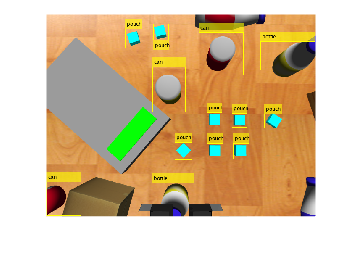

img = imread('D:\张昊逸\2023张昊逸\9月后\课件\上学期\Robotics Project\编程参考\test\imageFromGazebo\Image_20240120T002732.png');
[bboxes, scores, labels] = detect(trainedDetector,img,Threshold=0.7);
detectedImg = insertObjectAnnotation(img,"Rectangle",bboxes,labels);
figure
imshow(detectedImg)

Test with Annotation

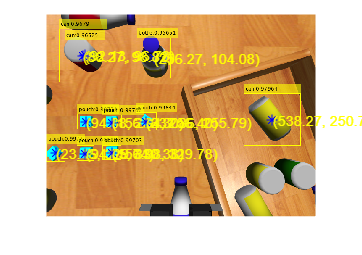

img = imread('D:\张昊逸\2023张昊逸\9月后\课件\上学期\Robotics Project\编程参考\test\imageFromGazebo\Image_20240120T002642.png');
[bboxes, scores, labels] = detect(trainedDetector, img);

%remove scores below 0.9 accuracy
high_score_indices = scores >= 0.9;
bboxes = bboxes(high_score_indices, :);
scores = scores(high_score_indices);
labels = labels(high_score_indices); 

classNames = trainedDetector.ClassNames;
labelStrs = classNames(labels);
annotations = strcat(labelStrs, ': ', string(scores));
I1 = insertObjectAnnotation(img, 'rectangle', bboxes, annotations);

[m, n] = size(bboxes);
centers = zeros(m, 2);
mat=zeros(m);
for i = 1:m
    centers(i, 1) = bboxes(i, 1) + (bboxes(i, 3) / 2);
    centers(i, 2) = bboxes(i, 2) + (bboxes(i, 4) / 2);
    y(i)=-centers(i,1);
    x(i)=centers(i,2);
end


figure;
imshow(I1);
hold on;
for i = 1:m
    plot(centers(i, 1), centers(i, 2), 'b*');
    text(centers(i, 1), centers(i, 2), sprintf('(%0.2f, %0.2f)', centers(i, 1), centers(i, 2)), 'Color', 'yellow', 'FontSize', 8);
end

Function

function data = preprocessData(data,targetSize)
for num = 1:size(data,1)
    I = data{num,1};
    imgSize = size(I);
    bboxes = data{num,2};
    I = im2single(imresize(I,targetSize(1:2)));
    scale = targetSize(1:2)./imgSize(1:2);
    bboxes = bboxresize(bboxes,scale);
    data(num,1:2) = {I,bboxes};
end
end